## 使用卷积平滑数据

平滑包含高频成分的二维数据。

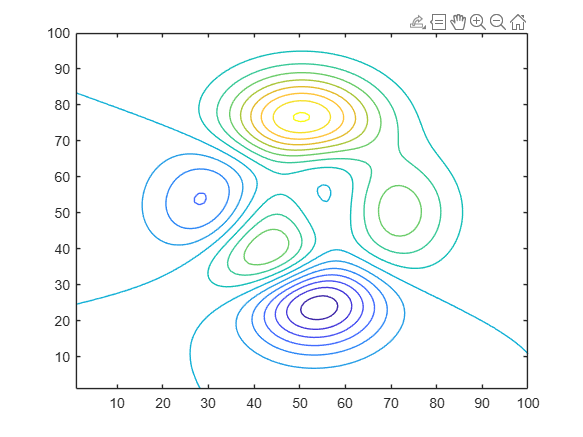

Z = peaks(100);
levels = -7:1:10;
contour(Z,levels)

注入一些随机噪声

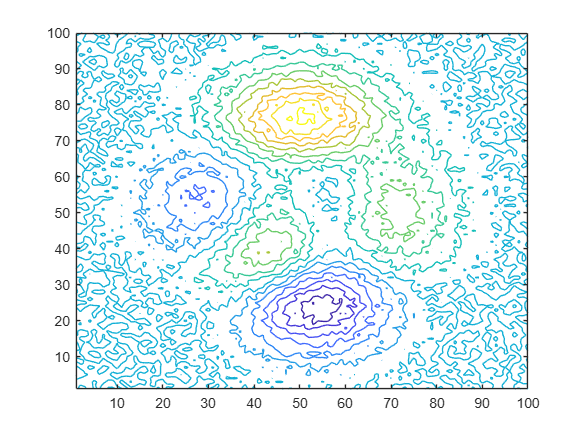

Z = peaks(100);
levels = -7:1:10;
Znoise = Z + rand(100) - 0.5;
contour(Znoise,levels)

MATLAB® 中的 `conv2`函数使用指定的核对二维数据进行卷积，核的元素定义了如何去除或增强原始数据的特征。

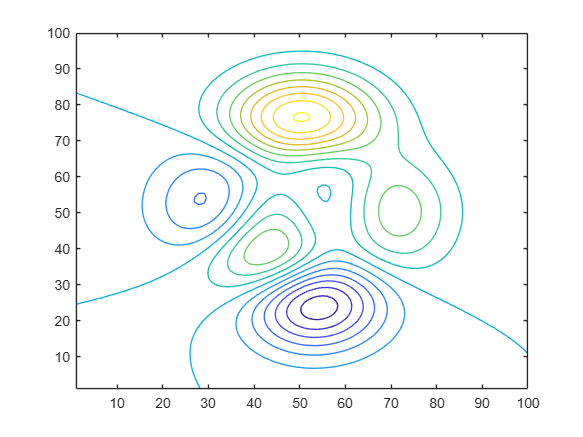

Z = peaks(100);
levels = -7:1:10;
contour(Z,levels)

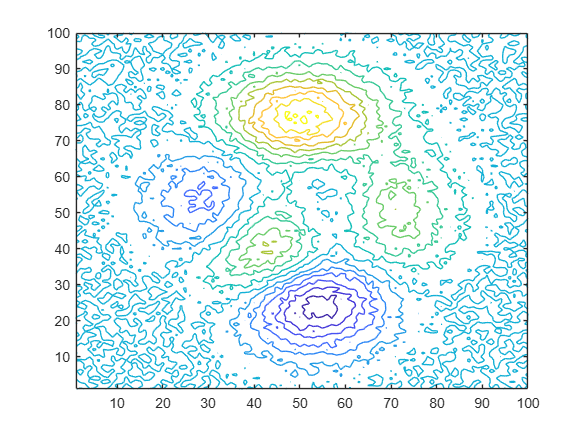

Znoise = Z + rand(100) - 0.5;
contour(Znoise,levels)

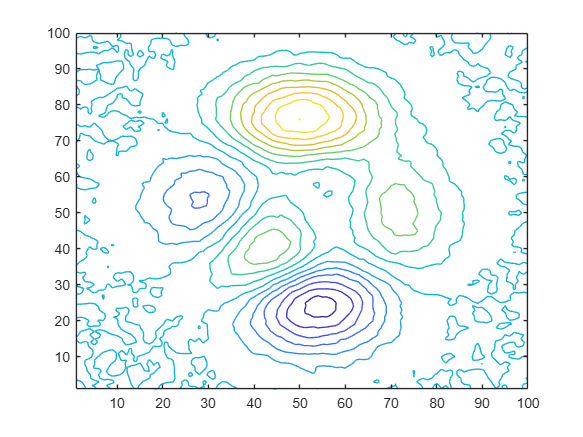

K = (1/9)*ones(3);
Zsmooth1 = conv2(Znoise,K,'same');
contour(Zsmooth1, levels)

• 说明

- 对于仅包含少量频率成分的数据，小尺寸的核可能足以实现平滑效果。

- 较大尺寸的核可以在调整频率响应时提供更高的精度，从而产生更平滑的输出结果。